%%NON VA TANTO BENE, SE PROVI ARTEMIS_ROAD ESPLODE, VEDI SE RIESCI A TROVARE ALTRO
% La modifica principale è che finchè quadprog ritorna vuoto lui
%%prova altre condizioni iniziali a caso tra -1 e 1 finchè non ne trova una
%%valida, ma non succede abbastanza spesso da essere un problema. Più che
%%altro c'è da cambiare myoptions.graddx credo(?) Lui suggerisce 2^-17, a
%%me sembra piccolo


clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
load eff_interpol.mat

my_cycle(1,:)=linspace(30,0,1001);
my_cycle(2,:)=[my_cycle(1,1:end-1)-my_cycle(1,2:end),0];
my_cycle(3,:)=3;

start=0;%Definisci l'istante iniziale
N=5; %Time horizon
SOC_START=0.55;

SOC=SOC_START*ones(N,1);
u_n=1*ones(N,1);
N_rounds=1;
N_it=1000;
%exitf = zeros(N_it*N_rounds,1);
driving_cycle=ARTEMIS;

u=zeros(1,N_it*N_rounds);
tic
x=zeros(N_rounds,1);
C=[eye(N);-eye(N)];
d=[-ones(N,1);-ones(N,1)];

myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-6;
myoptions.tolfun    	=	1e-12;
myoptions.tolX       	=	1e-12;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.tolconstr     =	1e-3;
myoptions.xsequence     =	'on';
myoptions.display       ='none';
        %%

for k=1:N_rounds
     %Se si vuole cambiare ciclo tra un round e l'altro
     %x(k)=rand;
     %driving_cycle=(x(k)<0.33)*ARTEMIS+(x(k)>=0.33)*ARTEMIS_road*(x(k)<=0.66)+(x(k)>0.66)*my_cycle;
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
       
        speed=driving_cycle(1,start+j:start+N-1+j);
        acceleration=driving_cycle(2,start+j:start+N-1+j);
        gear=driving_cycle(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
        myFullStateUpdate=@(u)my_full_horizon(u,SOC(2),StateUpdate);
        FullStateUpdate=@(u)full_horizon(u,SOC(2),StateUpdate);
        
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        [u_n,~,~,exitf(j),~,~]=myfmincon(myFullStateUpdate,[u_n(2:end);u_n(end)],[],[],C,d,0*N,8*N,myoptions);
        if exitf(j)<=0
            popoop=1;%[u_n]=myfmincon(myFullStateUpdate,[u_n(2:end),0]',[],[],C,d,1*N,4*N,myoptions);
        end

        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            fprintf("All'iterazione %d l'exitflag è %d ",j,exitf(j))
        end
    
        if rem(j,N_it/10)==0
            fprintf("Siamo al: %f percento dell'iterazione %d \n Ci ha messo %f \n",j/(N_it)*100,k,toc)
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Siamo al: 10.000000 percento dell'iterazione 1 
 Ci ha messo 4.796274 
Siamo al: 20.000000 percento dell'iterazione 1 
 Ci ha messo 3.320749 


Siamo al: 10.000000 percento dell'iterazione 1 
 Ci ha messo 7.893232 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    1.83193e-05   3.26887e-03   0.00000e+00    1.41866e-01   1.00000e+00    1.00000e+00              0
        1    8.43708e-05   3.26880e-03   0.00000e+00    1.41871e-01   2.04659e-05    1.38735e-02               2
        2    8.43666e-05   3.26880e-03   0.00000e+00    1.41871e-01   3.57867e-07    1.21660e-04               6
        3    8.43623e-05   3.26880e-03   0.00000e+00    1.41871e-01   4.86043e-07    1.67267e-04               4
        4    8.43617e-05   3.26880e-03   0.00000e+00    1.41871e-01   5.98912e-08    2.07142e-05               6
        5    8.43615e-05   3.26880e-03   0.00000e+00    1.41871e-01   2.56337e-08    7.51841e-06               6
        6    8.34246e-05   3.26880e-03   0.00000e+00    1.41871e-01   2.91580e-08    9.60518e-06               6
        7    8.34564e-05   3.26878e-03   0.00000e+00    1.41870e-01   6.20106e-06    8.04051e-04 

Siamo al: 20.000000 percento dell'iterazione 1 
 Ci ha messo 5.553011 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.67025e-03   3.58924e-05   0.00000e+00    3.18634e-14   1.00000e+00    1.00000e+00              0
        1    3.67025e-03   3.58924e-05   0.00000e+00    3.18634e-14   0.00000e+00    0.00000e+00              10
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.67025e-03   3.58924e-05   0.00000e+00    3.18634e-14   1.00000e+00    1.00000e+00              0
        1    3.67025e-03   3.58924e-05   0.00000e+00    3.18634e-14   0.00000e+00    0.00000e+00              10
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.67025e-03   3.58

Siamo al: 30.000000 percento dell'iterazione 1 
 Ci ha messo 7.107785 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    1.64230e-03   -6.99879e-05   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    1.64230e-03   -6.99879e-05   0.00000e+00    -0.00000e+00   0.00000e+00    2.48253e-16              14
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.32209e-03   -4.21740e-05   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    2.32209e-03   -4.21740e-05   0.00000e+00    -0.00000e+00   0.00000e+00    2.48253e-16              14
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.84368e-0

Siamo al: 40.000000 percento dell'iterazione 1 
 Ci ha messo 14.033093 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    4.81432e-02   -5.57823e-04   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    5.37632e-03   -5.57905e-04   0.00000e+00    -0.00000e+00   1.47480e-04    1.46954e-06               0
        2    4.27677e-02   -5.57905e-04   0.00000e+00    -0.00000e+00   0.00000e+00    1.50084e-15              13
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    6.12991e-02   -7.08660e-05   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    4.27049e-08   -7.08661e-05   0.00000e+00    -0.00000e+00   1.07997e-06    3.86281e-07               0
Local minimum possible, directional derivative smaller than tolerance. Constraints satisfied.
Iteration       N

Siamo al: 50.000000 percento dell'iterazione 1 
 Ci ha messo 9.190465 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.84327e-03   -2.73657e-05   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    2.84327e-03   -2.73657e-05   0.00000e+00    -0.00000e+00   0.00000e+00    1.09232e-15              13
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.28275e-03   2.27025e-05   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    3.28275e-03   2.27025e-05   0.00000e+00    -0.00000e+00   0.00000e+00    4.96507e-17              15
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.67022e-03 

Siamo al: 60.000000 percento dell'iterazione 1 
 Ci ha messo 8.458725 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.66973e-03   3.70584e-05   0.00000e+00    3.17746e-13   1.00000e+00    1.00000e+00              0
        1    3.66973e-03   3.70584e-05   0.00000e+00    3.17746e-13   0.00000e+00    0.00000e+00              10
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.66973e-03   3.70597e-05   0.00000e+00    3.17746e-13   1.00000e+00    1.00000e+00              0
        1    3.66973e-03   3.70597e-05   0.00000e+00    3.17746e-13   0.00000e+00    0.00000e+00              10
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.66973e-03   3.70

Siamo al: 70.000000 percento dell'iterazione 1 
 Ci ha messo 2.862334 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    5.08778e-03   4.74207e-05   0.00000e+00    1.85407e-14   1.00000e+00    1.00000e+00              0
        1    5.08778e-03   4.74207e-05   0.00000e+00    1.85407e-14   0.00000e+00    0.00000e+00              13
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.45116e-02   1.50233e-04   0.00000e+00    1.85407e-14   1.00000e+00    1.00000e+00              0
        1    5.93878e-11   1.50233e-04   0.00000e+00    0.00000e+00   8.13170e-12    1.85407e-14               0
Local minimum possible, directional derivative smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    3.92672e-02   

All'iterazione 788 l'exitflag è -1 

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    1.00247e-01   3.10508e-03   0.00000e+00   -8.97586e-01   1.00000e+00    1.00000e+00               0
        1    8.01958e-02   2.80572e-03   0.00000e+00   -2.77929e-01   9.64109e-02    2.05079e-01               1
        2    8.01954e-02   2.74781e-03   0.00000e+00   -1.79348e-01   2.06404e-02    1.43526e-01               1
        3    8.01950e-02   2.72652e-03   0.00000e+00    5.70566e-12   7.74787e-03    5.52022e-02               1
        4    8.89613e-05   2.72362e-03   0.00000e+00    3.80096e-12   1.06324e-03    2.36403e-02               0
        5    8.01953e-02   2.72020e-03   0.00000e+00    3.48732e-12   1.25541e-03    9.46089e-02               1
        6    8.25918e-05   2.71952e-03   0.00000e+00    1.00313e-10   2.51210e-04    4.46474e-02               0
        7    8.01961e-02   2.71839e-03   0.00000e+00    8.06247e-11   4.13884e-04    1.57403e-02

Siamo al: 80.000000 percento dell'iterazione 1 
 Ci ha messo 17.556517 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    6.73781e-04   8.19876e-04   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    7.02697e-02   7.52445e-04   0.00000e+00    -0.00000e+00   8.22445e-02    9.16681e-01               0
        2    6.98709e-02   7.52418e-04   0.00000e+00    -0.00000e+00   3.69515e-05    9.50365e-04               3
        3    7.03229e-02   7.52416e-04   0.00000e+00    -0.00000e+00   2.45397e-06    9.09860e-04               4
        4    3.63838e-04   7.52398e-04   0.00000e+00    -0.00000e+00   2.43142e-05    4.75679e-04               0
        5    5.60217e-02   7.52396e-04   0.00000e+00    -0.00000e+00   1.78653e-06    4.54745e-05               1
        6    6.95088e-02   7.52396e-04   0.00000e+00    -0.00000e+00   7.09133e-07    1.81919e-05               3
        7    5.60566e-02   7.52396e-04   0.00000e+00    -0.00000e+00   3.69275e-08    4.22

Siamo al: 90.000000 percento dell'iterazione 1 
 Ci ha messo 3.997986 


Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.18301e-04   -4.13835e-04   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    2.18301e-04   -4.13835e-04   0.00000e+00    -0.00000e+00   0.00000e+00    7.02167e-17              14
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.09168e-04   -3.95211e-04   0.00000e+00    -0.00000e+00   1.00000e+00    1.00000e+00              0
        1    2.09168e-04   -3.95211e-04   0.00000e+00    -0.00000e+00   0.00000e+00    0.00000e+00              15
Local minimum possible, relative step size smaller than tolerance. Constraints satisfied.
Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    2.91304e-0

All'iterazione 929 l'exitflag è -1 

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    4.67041e-02   1.79283e-03   0.00000e+00    1.18905e-13   1.00000e+00    1.00000e+00              0
        1    3.73635e-02   1.78477e-03   0.00000e+00    6.93289e-11   4.49640e-03    1.28327e-01               1
        2    3.73633e-02   1.78356e-03   0.00000e+00    5.74202e-11   6.78296e-04    2.94517e-02               1
        3    6.72086e-05   1.78048e-03   0.00000e+00    8.96860e-12   1.72512e-03    3.35160e-02               0
        4    3.73638e-02   1.77674e-03   0.00000e+00    5.94556e-11   2.10272e-03    4.02013e-02               1
        5    3.73632e-02   1.77667e-03   0.00000e+00    4.75645e-11   3.73236e-05    6.68803e-03               1
        6    5.20554e-05   1.77654e-03   0.00000e+00    1.05631e-09   7.48361e-05    3.77953e-03               0
        7    2.95686e-05   1.77648e-03   0.00000e+00    2.76080e-09   3.03026e-05    3.31923e-03 

toc

Elapsed time is 18.294403 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];
acceleration=[];
gear=[];

for i=1:54
    %driving_cycle=(x(i)<0.33)*ARTEMIS+(x(i)>=0.33)*ARTEMIS_road*(x(i)<=0.66)+(x(i)>0.66)*my_cycle;
    speed=[speed,driving_cycle(1,start+1:start+N+j)];
    acceleration=[acceleration,driving_cycle(2,start+1:start+N+j)];
    gear=[gear,driving_cycle(3,start+1:start+N+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
FullStateUpdate=@(u)full_horizon(u,SOC_START,StateUpdate);
[cost,SOC2plot,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,SOC_START,StateUpdate);
tot_c=sum(sum(c<=0))/(4*length(c))

tot_c = 0.5002

tot_ceq=sum(abs(ceq)<=myoptions.tolconstr)/length(ceq)

tot_ceq = 0.9670

tot_mf=sum(mf)

tot_mf = 0.0620

tot_soc_var=SOC_START-SOC(end)

tot_soc_var = 0.0651

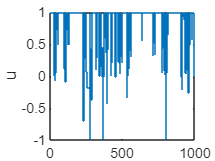

stairs(u)
ylabel('u')

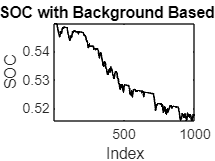

figure
hold on
num_segments = length(x); % Number of regions
segment_size = length(SOC) / num_segments; % Elements per segment
colors = [1 1 0; 1 0 0; 0 1 0]; % Define colors (red, green, blue)

% for i = 1:num_segments
%     % Define segment range
%     x_start = (i - 1) * segment_size + 1;
%     x_end = i * segment_size;
% 
%     % Determine background color based on x(i)
%     if x(i) < 0.33
%         bg_color = colors(1, :); % Light red
%     elseif x(i) < 0.66
%         bg_color = colors(2, :); % Light green
%     else
%         bg_color = colors(3, :); % Light blue
%     end
% 
%     % Plot background as a filled rectangle
%     fill([x_start x_end x_end x_start], [min(SOC) min(SOC) max(SOC) max(SOC)], ...
%         bg_color, 'EdgeColor', 'none');
% end

% Plot the SOC data on top
plot(SOC2plot, 'k', 'LineWidth', 1);

% Additional plot settings
xlim([1, length(SOC2plot)]);
ylim([min(SOC2plot), max(SOC2plot)]);
xlabel('Index');
ylabel('SOC');
title('SOC with Background Based on x');
box on;
hold off

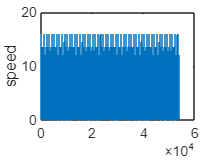


stairs(speed)
ylabel('speed')

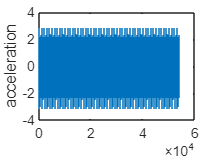

stairs(acceleration)
ylabel('acceleration')

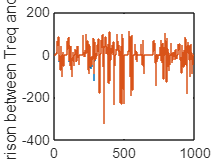

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')